plot(TURQUOISEvoltage,TURQUOISEcurrent,'.')
hold on,


%%CREATING ERRORBARS
xneg=0.001.*[1 1 1 1 1 1 1 1 1 1];
xpos=xneg;
yneg=(0.2e-13).*[1 1 1 1 1 1 1 1 1 1];
ypos=yneg;
errorbar(TURQUOISEvoltage,TURQUOISEcurrent,yneg,ypos,xneg,xpos,'o')


%%NEGATIVE SIDE FIT
%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =      -2.000E-13  (-1.667e-12, 1.267e-12)  (\pm 0.734E-12)
  %     p2 =   6.333E-14  (-5.996e-13, 7.263e-13)  (\pm 3.315E-13)

%Goodness of fit:
 % SSE: 6.667e-29
  %R-square: 0.75
  %Adjusted R-square: 0.5
  %RMSE: 8.165e-15
p1 =      -2e-13 

p1 = -2.0000e-13

p2 =   6.333e-14 

p2 = 6.3330e-14

 f = p1*TURQUOISEvoltage + p2

f = 	1.0e+-13 *

    0.5333    0.4333    0.3333    0.2333    0.1333    0.0333   -0.0667   -0.1667   -0.2667   -0.3667


 plot(TURQUOISEvoltage,f,'m')
 
 %%POSITIVE SIDE FIT
 %Linear model Poly1:
  %   g(x) = p3*x + p4
%Coefficients (with e95% confidence bounds):
 %      p3 =      -4.000E-13  (-4e-13, -4e-13)  (\pm 0.001E-13)
  %     p4 =       1.000E-13  (1e-13, 1e-13)    (\pm 0.001E-13)

%Goodness of fit:
 % SSE: 1.882e-57
  %R-square: 1
 % Adjusted R-square: 1
  %RMSE: 3.067e-29
  
  p3 =      -4e-13  

p3 = -4.0000e-13

  p4 =       1e-13

p4 = 1.0000e-13

  g= p3*TURQUOISEvoltage + p4

g = 	1.0e+-13 *

    0.8000    0.6000    0.4000    0.2000         0   -0.2000   -0.4000   -0.6000   -0.8000   -1.0000


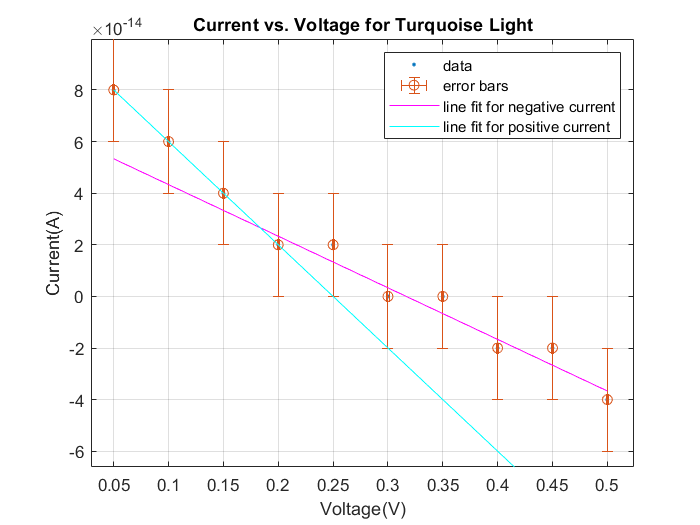

  plot(TURQUOISEvoltage,g,'c')
  
  grid on
  
  title('Current vs. Voltage for Turquoise Light')
xlabel('Voltage(V)')
ylabel('Current(A)')
legend({'data','error bars','line fit for negative current','line fit for positive current'})

xlim([0.029 0.524])
ylim([-0.000000000000066 0.000000000000100])